## Quadruped Matlab Control System

Description of the purpose of the live script.(hint this is used to generate an array of angles for some postion controlled motors for a quadruped, a robot with four legs. this is to control two joints for a leg that is angle controlled. this produces an output that can be copied to be used in other code. 

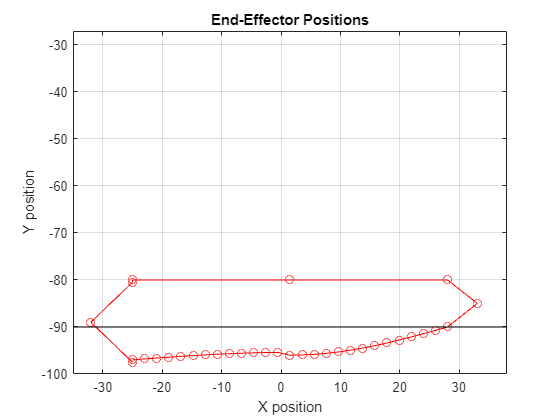

% Define the lengths of the femur and tibia bone
L1 = 75;  % length of femur bone
L2 = 29;  % length of tibia bone

%use function
num_points = 12*3;
x_min = -25;
x_max = 28;
[x_values, y_values] = Automation_pattern(num_points,x_min,x_max);



% [x_values, y_values] = triangular2_path(30,num_points,-30);
% [x_values, y_values] = square_path(10,num_points,-20);
% x_values = [0,0];
% y_values = [-99+0.0001,-99+0.0001];

% Compute the end-effector positions along the curve
end_effector_pos = zeros(2, length(x_values));
for i = 1:length(x_values)
    % Evaluate the curve function at the current parameter value
    x = x_values(i);
    y = y_values(i);
    end_effector_pos(:,i) = [x; y];
end



% Plot the end-effector positions
figure;
plot(end_effector_pos(1,:), end_effector_pos(2,:), 'ro-');
grid on;
xlim([-100, 100]);  % adjust as needed
ylim([-100, 100]);  % adjust as needed
xlabel('X position');
ylabel('Y position');
title('End-Effector Positions');
hold on;
% Define the x-coordinates for the line
x = [-100, 100];
% Define the ground
y = [-90, -90];
% Plot the line
plot(x, y, 'k-');

xlim([x_min-10 x_max+10])
ylim([-100.0 -27.1])

% Initialize arrays to store the computed angles
theta1 = zeros(1, length(x_values));
theta2 = zeros(1, length(x_values));


% Compute the inverse kinematics solution for each point along the curve
for i = 1:length(x_values)
    % Compute the distance between the end-effector and the knee joint
    d = norm(end_effector_pos(:,i));
    
    % Determine whether the end-effector is above or below the knee joint
    if d > L1 + L2
        % End-effector is out of reach
        error("No solution exists for the given end-effector position");
    elseif d < abs(L1 - L2)
        % End-effector is too close to the joint
        error("No solution exists for the given end-effector position");
    else
        % End-effector is within reach
        cos_theta2 = (-L1^2 - L2^2 + d^2) / (2 * L1 * L2);
        if abs(cos_theta2) > 1
            % No solution exists for the given end-effector position
            error("No solution exists for the given end-effector position");
        end
        if end_effector_pos(2,i) >= 0
            % End-effector is above the knee joint
            theta2(i) = acos(cos_theta2);
            theta1(i) = atan2(end_effector_pos(2,i), end_effector_pos(1,i)) - atan2(L2*sin(theta2(i)), L1+L2*cos(theta2(i)));
        else
            % End-effector is below the knee joint
            theta2(i) = -acos(cos_theta2);
            A=end_effector_pos(2,i)*(L1+L2*cos(theta2(i)))-end_effector_pos(1,i)*L2*sin(theta2(i));
            B=end_effector_pos(1,i)*(L1+L2*cos(theta2(i)))+end_effector_pos(2,i)*L2*sin(theta2(i));
        if B > 0
        theta1(i) = atan(A/B);
        else
        theta1(i) = atan(A/B) - pi;
        end
        end
    end
end

% Convert angles to degrees and adjust negative values
% Step 1: Rotate to align zero with North
theta1a=theta1-pi/2;
% Step 2: Reverse the direction of the angle
theta1a = -theta1a;

% Step 3: Make the angle positive
if theta1a < 0
    theta1a = theta1a + 360;
end

theta2a = theta2 + pi;

theta1_deg = flip(rad2deg(theta1a));
theta2_deg = flip(rad2deg(theta2a));

% Create string representations of the arrays
theta1_str = sprintf("int FemerAngle[] = {%d", round(theta1_deg(1)));
theta2_str = sprintf("int TibeaAngle[] = {%d", round(theta2_deg(1)));
for i = 2:length(theta1_deg)
    theta1_str = strcat(theta1_str, sprintf(",%d", round(theta1_deg(i))));
    theta2_str = strcat(theta2_str, sprintf(",%d", round(theta2_deg(i))));
end
theta1_str = strcat(theta1_str, "};");
theta2_str = strcat(theta2_str, "};");

% Display the results
% fprintf("Inverse Kinematics Solution:\n");
fprintf("%s\n", theta1_str)

int FemerAngle[] = {185,185,177,177,158,141,141,142,148,148,149,151,152,154,155,156,158,159,161,162,163,164,166,166,168,169,170,172,173,175,176,178,180,181,183,185};


fprintf("%s\n", theta2_str)

int TibeaAngle[] = {147,125,98,97,89,100,100,115,124,124,124,125,125,126,126,127,128,128,129,129,129,129,129,127,128,128,129,129,131,132,133,135,137,139,142,145};


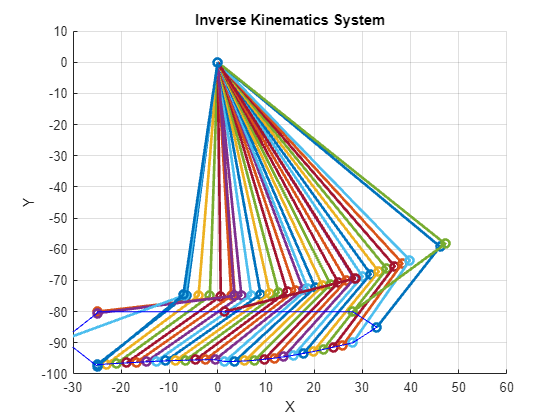


% Plot the end-effector positions and the links
% figure();
% hold on;
% plot(end_effector_pos(1,:), end_effector_pos(2,:), '-o', 'LineWidth', 2, 'MarkerSize', 8);
% for i = 1:length(theta1_deg)
%     % Compute the position of the knee joint
%     knee_pos = [L1 * cos(theta1(i)), L1 * sin(theta1(i))];
%     theta1_deg = rad2deg(theta1)
%     theta2_deg = rad2deg(theta2)
%     % Compute the position of the foot joint to x and y
%     % foot_pos = [L1 * cos(theta1(i)) + L2 * cos(theta1(i)+theta2(i)), L1 * sin(theta1(i)) + L2 * sin(theta1(i)+theta2(i))];
%     foot_pos = [knee_pos(1) + L2 * cos(theta1(i) + theta2(i)); knee_pos(2) + L2 * sin(theta1(i) + theta2(i))];
% 
%     % Plot the links
%     plot([0, knee_pos(1), foot_pos(1)], [0, knee_pos(2), foot_pos(2)], 'LineWidth', 2);
% end
% 
% figure;
% plot([0, knee_pos(1), foot_pos(1)], [0, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2, 'MarkerSize', 8);
% xlim([-100, 100]);  % adjust as needed
% ylim([-100, 100]);  % adjust as needed
% title('2-DOF System');
% xlabel('X');
% ylabel('Y');
% grid on;
figure;
grid on; 
xlim([-30, 60]);  % adjust as needed
ylim([-100, 10]);  % adjust as needed
title('Inverse Kinematics System');
xlabel('X');
ylabel('Y');
hold on;

for i = 1:length(theta1_deg)
    % Compute the position of the knee joint
    knee_pos = [L1 * cos(theta1(i)), L1 * sin(theta1(i))];
    theta1_deg = rad2deg(theta1);
    theta2_deg = rad2deg(theta2);
    % Compute the position of the foot joint to x and y
    foot_pos = [knee_pos(1) + L2 * cos(theta1(i) + theta2(i)); knee_pos(2) + L2 * sin(theta1(i) + theta2(i))];

    % Plot the links
    plot([0, knee_pos(1), foot_pos(1)], [0, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2);
    plot(end_effector_pos(1,:), end_effector_pos(2,:), 'b-');
end
hold off;

% figure;
% grid on; 
% xlim([-100, 340]);  % adjust as needed
% ylim([-200, 200]);  % adjust as needed
% title('Forward Kinematics System');
% xlabel('X');
% ylabel('Y');
% hold on;
% 
% offset_x = 240; % offset in x direction
% offset_y = 100; % offset in y direction
% 
% % Angle data for each leg
% theta1_strBR = "int BRFemerAngle[] = {180,225,220,215,135,130,125,181,182};";
% theta2_strBR = "int BRTibeaAngle[] =  {180,225,220,215,135,130,125,181,182};";
% 
% theta1_strFL = "int FLFemerAngle[] = {180,225,220,135,134,133,132,181,179};";
% theta2_strFL = "int FLTibeaAngle[] =  {180,225,220,135,134,133,132,181,179};";
% 
% theta1_strBL = "int BLFemerAngle[] = {135,135,180,180,180,225,225,225,225};";
% theta2_strBL = "int BLTibeaAngle[] = {135,135,180,180,180,225,225,225,225};";
% 
% theta1_strFR = "int FRFemerAngle[] = {135,135,180,180,180,225,225,225,135};";
% theta2_strFR = "int FRTibeaAngle[] = {135,135,180,180,180,225,225,225,135};";
% 
% % Parse angle data
% [theta1_radBR, theta2_radBR] = parseStringArray(theta1_strBR, theta2_strBR);
% [theta1_radFL, theta2_radFL] = parseStringArray(theta1_strFL, theta2_strFL);
% [theta1_radBL, theta2_radBL] = parseStringArray(theta1_strBL, theta2_strBL);
% [theta1_radFR, theta2_radFR] = parseStringArray(theta1_strFR, theta2_strFR);
% 
% % Ensure arrays have the same length
% assert(length(theta1_radBR) == length(theta2_radBR) && length(theta1_radFL) == length(theta2_radFL) && length(theta1_radBL) == length(theta2_radBL) && length(theta1_radFR) == length(theta2_radFR), 'Angle arrays must have the same length');
% 
% for i = 1:length(theta1_radBR)
%     % Compute and plot positions for each leg
%     [knee_pos, foot_pos] = computePositions(theta1_radBR(i), theta2_radBR(i), offset_x, offset_y);
%     back_right_leg = plot([0 + offset_x, knee_pos(1), foot_pos(1)], [0 + offset_y, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2, 'Color', 'b');
% 
%     [knee_pos, foot_pos] = computePositions(theta1_radFL(i), theta2_radFL(i), 0, -offset_y);
%     front_left_leg = plot([0, knee_pos(1), foot_pos(1)], [0 - offset_y, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2, 'Color', 'r');
% 
%     [knee_pos, foot_pos] = computePositions(theta1_radBL(i), theta2_radBL(i), 0, offset_y);
%     back_left_leg = plot([0, knee_pos(1), foot_pos(1)], [0 + offset_y, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2, 'Color', 'g');
% 
%     [knee_pos, foot_pos] = computePositions(theta1_radFR(i), theta2_radFR(i), offset_x, -offset_y);
%     front_right_leg = plot([0 + offset_x, knee_pos(1), foot_pos(1)], [0 - offset_y, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2, 'Color', 'c');
% end
% 
% legend([back_right_leg, front_left_leg, back_left_leg, front_right_leg], {'Back Right leg', 'Front Left leg', 'Back Left leg', 'Front Right leg'});
% hold off;
% % Define the range of the slider
% slider_range = 1:length(theta1_deg);
% 
% % Create a figure for the animation
% figure;
% grid on;
% xlim([-100, 100]);  % adjust as needed
% ylim([-100, 100]);  % adjust as needed
% title('Inverse Kinematics System');
% xlabel('X');
% ylabel('Y');
% hold on;

% % Create a slider to control the iteration
% slider = uicontrol('Style', 'slider', 'Units', 'normalized', 'Position', [0.1 0.05 0.8 0.05], 'Min', slider_range(1), 'Max', slider_range(end), 'Value', slider_range(1), 'SliderStep', [1/(length(slider_range)-1) 1/(length(slider_range)-1)], ...
%     'Callback', @(src,~) updatePlot(round(src.Value), theta1_deg, theta2_deg));
% 
% % Initialize the plot with the initial iteration
% updatePlot(slider_range(1), theta1_deg, theta2_deg, L1, L2);



function updatePlot(iteration, theta1, theta2,L1,L2)
    % Clear the previous plot
    cla;
    
    % % Define the lengths of the femur and tibia bone
    % L1 = 73;  % length of femur bone
    % L2 = 26;  % length of tibia bone
    
    % Compute the position of the knee joint
    knee_pos = [L1 * cos(deg2rad(theta1(end-iteration+1))), L1 * sin(deg2rad(theta1(end-iteration+1)))];
    
    % Compute the position of the foot joint to x and y
    foot_pos = [knee_pos(1) + L2 * cos(deg2rad(theta1(end-iteration+1) + theta2(end-iteration+1))), knee_pos(2) + L2 * sin(deg2rad(theta1(end-iteration+1) + theta2(end-iteration+1)))];

    % Plot the links for the current iteration
    plot([0, knee_pos(1), foot_pos(1)], [0, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2);
    
    % Update the plot title with the current iteration
    title(['Inverse Kinematics System (Iteration: ' num2str(iteration) ')']);
    
    % Check if the end of the slider is reached
    if iteration == length(theta1)
        % Reset the slider to the beginning
        set(slider, 'Value', slider_range(1));
    end
end


function [knee_pos, foot_pos] = computePositions(theta1_rad, theta2_rad, offset_x, offset_y)
    % Compute the position of the knee joint
    % Define the lengths of the femur and tibia bone
L1 = 73;  % length of femur bone
L2 = 26;  % length of tibia bone

    knee_pos = [L1 * cos(theta1_rad) + offset_x, L1 * sin(theta1_rad) + offset_y];
    % Compute the position of the foot joint to x and y
    foot_pos = [knee_pos(1) + L2 * cos(theta1_rad + theta2_rad), knee_pos(2) + L2 * sin(theta1_rad + theta2_rad)];
end

function [theta1_rad, theta2_rad] = parseStringArray(theta1_str, theta2_str)
    % Parse the input strings to extract the arrays of angles
    theta1_deg = str2double(regexp(theta1_str, '\d+', 'match'));
    theta2_deg = str2double(regexp(theta2_str, '\d+', 'match'));

    % Convert angles from degrees to radians
    theta1_rad = deg2rad(theta1_deg);
    theta2_rad = deg2rad(theta2_deg);

    % adjust for the specific kinematic transformation in the original code
    % Step 1: Make the angle negative
    theta1_rad = -theta1_rad;

    % Step 2: Rotate to align zero with North
    theta1_rad = theta1_rad + pi/2;

    % Step 3: Make the angle positive
    theta1_rad = mod(theta1_rad, 2*pi);

    % For theta2 subtract pi
    theta2_rad = theta2_rad - pi;
end


% function [x_values, y_values] = oblong_shape(num_points,x_min,x_max)
% % Define the x and y values for the first straight line
% x_values1 = linspace(x_min, x_max, num_points/12); 
% y_values1 = -70*ones(1,num_points/12);
% 
% % Define the x and y values for the curve connecting (30,-50) to (30,-30)
% th1 = -pi/2:pi/((num_points/12)-1):pi/2;
% x_values2 = x_max + 10*cos(th1);
% y_values2 = -70 + 10*sin(th1);
% 
% % Define the x and y values for the second straight line
% x_values3 = linspace(x_max, x_min, 9*num_points/12);
% y_values3 = -70*ones(1,9*num_points/12);
% 
% % Define the x and y values for the curve connecting (30,-30) to (30,-50)
% th2 = pi/2:pi/((num_points/12)-1):3*pi/2;
% x_values4 = x_min + 10*cos(th2);
% y_values4 = -80 - 10*sin(th2);
% 
% % Combine the x and y values into one array
% x_values = [x_values1, x_values2, x_values3, x_values4];
% y_values = [y_values1, flip(y_values2), y_values3, y_values4];
% % x_values = [x_values1, x_values2, x_values3, x_values4];
% % y_values = [y_values1];
% end

function [x_values, y_values] = oblong_shape(num_points,x_min,x_max)
% Define the x and y values for the first straight line
% x_values1 = linspace(x_min, x_max, 9*num_points/12); 
% y_values1 = -90*ones(1,9*num_points/12);
    % Define the x and y values for the smiley face line
    % x_values1 = linspace(x_min, x_max, fix(num_points));
    % y_values1 = -90 * ones(1, fix(num_points));
        % Define the x and y values for the curved part of the smiley face
    x_values1 = linspace(x_min + (x_max - x_min) / 4, x_max - (x_max - x_min) / 4, fix(3*num_points/12));
    y_values1 = -40 * sin(pi * (x_values1 - x_min) / (x_max - x_min));

% Define the x and y values for the curve connecting (30,-50) to (30,-30)
th1 = -pi/2:pi/((num_points/12)-1):pi/2;
x_values2 = x_max + 5*cos(th1);
y_values2 = -85 + 5*sin(th1);

% Define the x and y values for the second straight line
x_values3 = linspace(x_max, x_min, num_points/12);
y_values3 = -80*ones(1,num_points/12);

% Define the x and y values for the curve connecting (30,-30) to (30,-50)
th2 = pi/2:pi/((num_points/12)-1):3*pi/2;
x_values4 = x_min + 5*cos(th2);
y_values4 = -85 - 5*sin(th2);

% Combine the x and y values into one array
x_values = [x_values1, x_values2, x_values3, x_values4];
y_values = [y_values1, y_values2, y_values3, flip(y_values4)];
end

## Automation function


function [x_values, y_values] = Automation_pattern(num_points,x_min,x_max)
% Define the x and y values for the first straight line
x_values1 = linspace(x_min, x_max, 9*num_points/12); 
    % Define the middle point of x_values1
    mid_point = floor(length(x_values1)/2);
    
    % First half of x_values1
    first_x_values1 = x_values1(1:mid_point);
    
    % Second half of x_values1
    second_x_values1 = x_values1(mid_point+1:end);
    
    % Define the y values for the first half of the x values
    first_y_values1 = (1.6 * sin(pi * (first_x_values1 - x_min) / (x_max - x_min))) -97;
    
    % Define the y values for the second half of the x values
    second_y_values1 = (-6 * sin(pi * (second_x_values1 - x_min) / (x_max - x_min)))-90;
    % Combine the x and y values into one array
    x_values1 = [first_x_values1, second_x_values1];
    y_values1 = [first_y_values1, second_y_values1];

% Define the x and y values for the curve connecting (30,-50) to (30,-30)
% x_values2 = linspace(50, 40, num_points/12);  % Adjust the range and number of points as needed
% y_values2 = -(x_values2 * tand(45))-40;
th1 = -pi/2:pi/((num_points/12)-1):pi/2;

x_values2 = x_max + 5*cos(th1);
y_values2 = -85 + 5*sin(th1);
% Assuming you have defined x_max and th1 previously

% % Calculate the full arrays for x_values2 and y_values2
% x_values2_plot1 = x_max + 5*cos(th1);
% y_values2_plot1 = -85 + 5*sin(th1);
% x_values2_plot2 = x_max - 5*cos(th1);
% y_values2_plot2 = -85 + 5*sin(th1);
% 
% % Determine the midpoint index
% midpoint = round(length(x_values2_plot2) / 2);
% 
% % Slice the arrays to keep only the first half
% first_x_values2 = x_values2_plot2(1:midpoint);
% first_y_values2 = y_values2_plot2(1:midpoint);
% 
% % Concatenate the first half with the second half
% second_x_values2 = x_values2_plot1(midpoint+1:end);
% second_y_values2 = y_values2_plot1(midpoint+1:end);
% 
% % Concatenate the first and second halves
% x_values2 = [first_x_values2, second_x_values2];
% y_values2 = [first_y_values2, second_y_values2];



% Define the x and y values for the second straight line
x_values3 = linspace(x_max, x_min, num_points/12);
y_values3 = -80*ones(1,num_points/12);

% Define the x and y values for the curve connecting (30,-30) to (30,-50)
th2 = pi/2:pi/((num_points/12)-1):3*pi/2;
x_values4 = x_min + 7*cos(th2);
y_values4 = -89 - 8.5*sin(th2);

% Combine the x and y values into one array
x_values = [x_values1, x_values2, x_values3, x_values4];
y_values = [y_values1, y_values2, y_values3, flip(y_values4)];
end

function [x_values, y_values] = square_path(side_length, num_points, y_offset)
    % Break up the total number of points into four segments
    points_per_segment = num_points / 4;

    % Define the x and y values for each of the four edges of the square
    x_values1 = linspace(-side_length/2, side_length/2, points_per_segment);
    y_values1 = (-side_length/2 + y_offset) * ones(1, points_per_segment);

    x_values2 = side_length/2 * ones(1, points_per_segment);
    y_values2 = linspace(-side_length/2 + y_offset, side_length/2 + y_offset, points_per_segment);

    x_values3 = linspace(side_length/2, -side_length/2, points_per_segment);
    y_values3 = (side_length/2 + y_offset) * ones(1, points_per_segment);

    x_values4 = -side_length/2 * ones(1, points_per_segment);
    y_values4 = linspace(side_length/2 + y_offset, -side_length/2 + y_offset, points_per_segment);

    % Combine the x and y values into one array
    x_values = [x_values1, x_values2, x_values3, x_values4];
    y_values = [y_values1, y_values2, y_values3, y_values4];
end

function [x_values, y_values] = triangular_path(base_length, height, num_points)
    % Break up the total number of points into three segments
    points_per_segment = num_points / 3;

    % Define the x and y values for each of the three edges of the triangle
    x_values1 = linspace(-base_length/2, base_length/2, points_per_segment);
    y_values1 = -height/2 * ones(1, points_per_segment);

    x_values2 = linspace(base_length/2, -base_length/2, points_per_segment);
    y_values2 = linspace(-height/2, height/2, points_per_segment);

    x_values3 = -base_length/2 * ones(1, points_per_segment);
    y_values3 = linspace(height/2, -height/2, points_per_segment);

    % Combine the x and y values into one array
    x_values = [x_values1, x_values2, x_values3];
    y_values = [y_values1, y_values2, y_values3];
end
function [x_values, y_values] = triangular2_path(base_length, num_points, y_offset)
    % Break up the total number of points into three segments
    points_per_segment = num_points / 3;

    % Calculate the height of the equilateral triangle
    height = sqrt(3) / 2 * base_length;

    % Define the x and y values for each of the three edges of the triangle
    x_values1 = linspace(-base_length/2, base_length/2, points_per_segment);
    y_values1 = (-height/2 + y_offset) * ones(1, points_per_segment);

    x_values2 = linspace(base_length/2, -base_length/2, points_per_segment);
    y_values2 = linspace(-height/2 + y_offset, height/2 + y_offset, points_per_segment);

    x_values3 = -base_length/2 * ones(1, points_per_segment);
    y_values3 = linspace(height/2 + y_offset, -height/2 + y_offset, points_per_segment);

    % Combine the x and y values into one array
    x_values = [x_values1, x_values2, x_values3];
    y_values = [y_values1, y_values2, y_values3];
end

